File: 1, Signal: 1, Signal: 1, R2: 1 
File: 1, Signal: 1, Signal: 2, R2: 0.116 
File: 1, Signal: 1, Signal: 3, R2: 0.0773 
File: 1, Signal: 1, Signal: 4, R2: 0.00211 
File: 1, Signal: 1, Signal: 5, R2: 0.0699 
File: 1, Signal: 1, Signal: 6, R2: 0.0139 
File: 1, Signal: 1, Signal: 7, R2: 0.163 
File: 1, Signal: 1, Signal: 8, R2: 0.137 
File: 1, Signal: 1, Signal: 9, R2: 0.00184 
File: 1, Signal: 1, Signal: 10, R2: 0.00962 
File: 1, Signal: 1, Signal: 11, R2: -Inf 
File: 1, Signal: 1, Signal: 12, R2: 0.045 
File: 1, Signal: 2, Signal: 2, R2: 1 
File: 1, Signal: 2, Signal: 3, R2: 0.000458 
File: 1, Signal: 2, Signal: 4, R2: 0.00431 
File: 1, Signal: 2, Signal: 5, R2: 0.000379 
File: 1, Signal: 2, Signal: 6, R2: 0.00326 


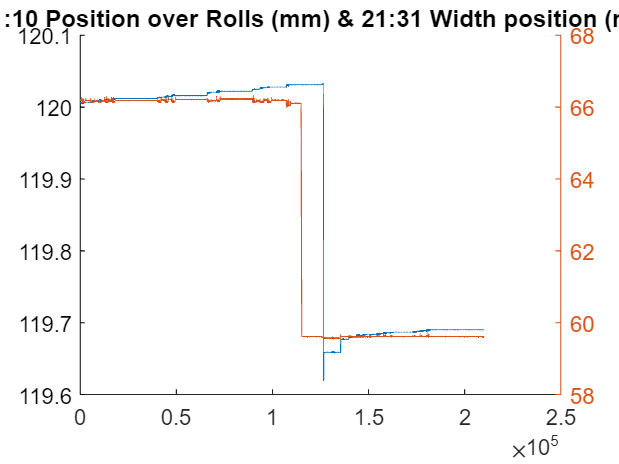

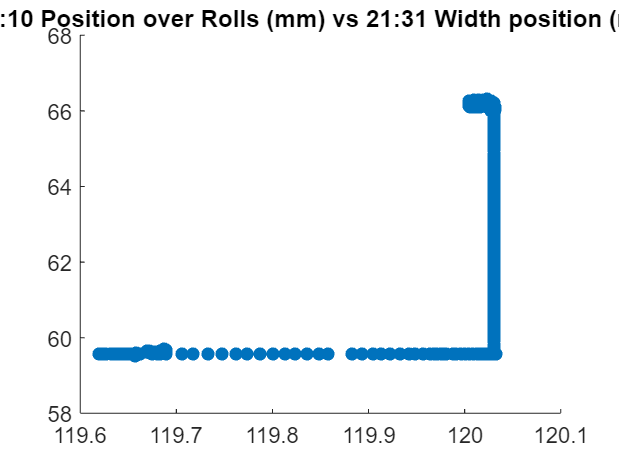

File: 1, Signal: 2, Signal: 7, R2: 0.783 


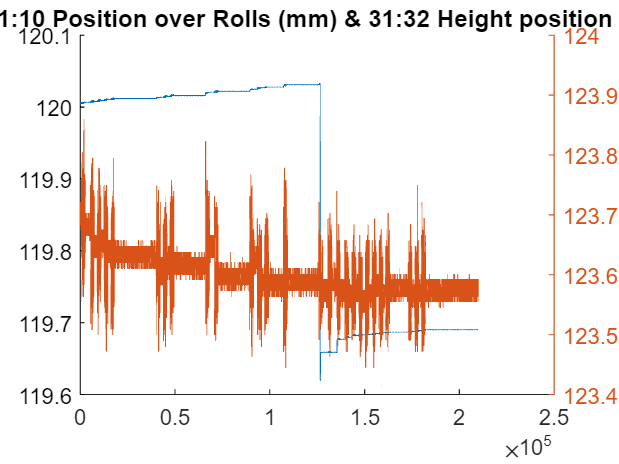

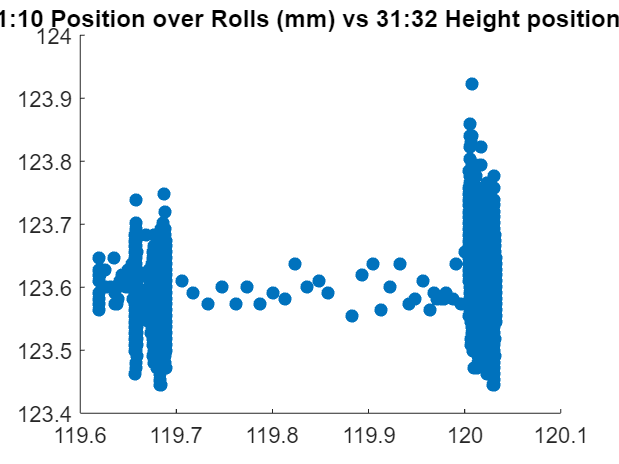

File: 1, Signal: 2, Signal: 8, R2: 0.298 


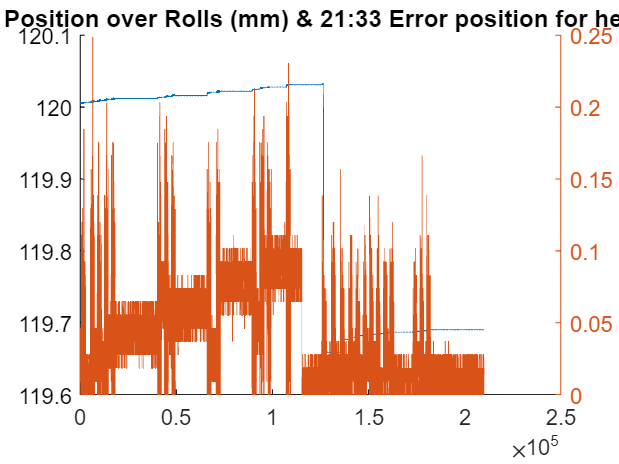

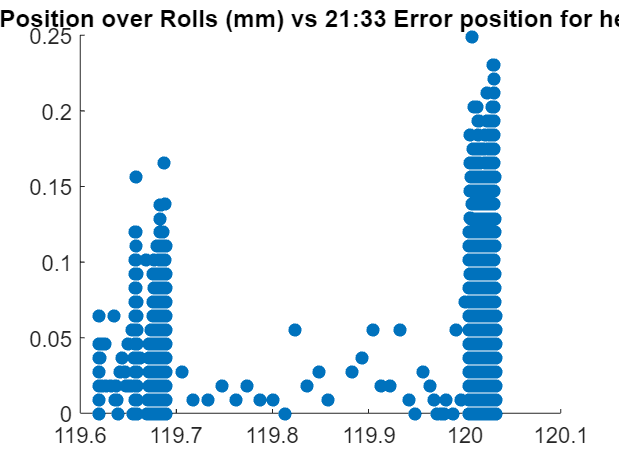

File: 1, Signal: 2, Signal: 9, R2: 0.359 
File: 1, Signal: 2, Signal: 10, R2: 0.0743 
File: 1, Signal: 2, Signal: 11, R2: -Inf 
File: 1, Signal: 2, Signal: 12, R2: 0.0053 
File: 1, Signal: 3, Signal: 3, R2: 1 
File: 1, Signal: 3, Signal: 4, R2: 0.113 
File: 1, Signal: 3, Signal: 5, R2: 0.996 


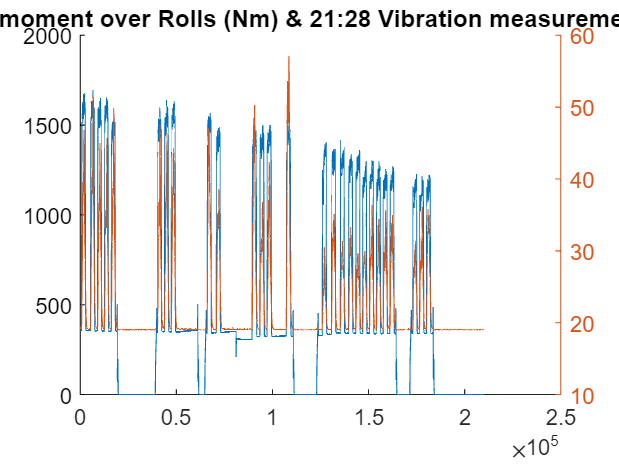

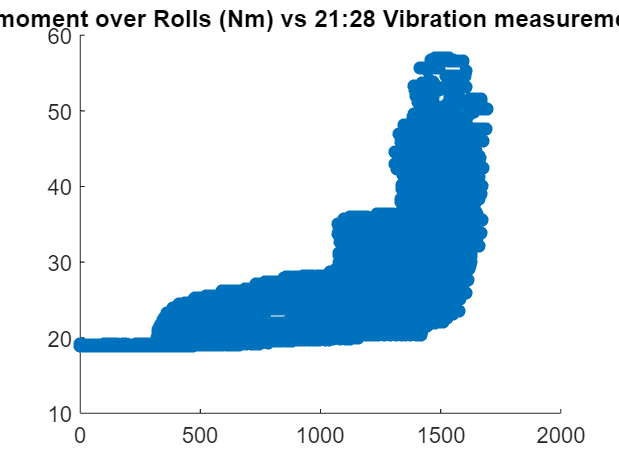

File: 1, Signal: 3, Signal: 6, R2: 0.725 
File: 1, Signal: 3, Signal: 7, R2: 0.0102 
File: 1, Signal: 3, Signal: 8, R2: 0.043 
File: 1, Signal: 3, Signal: 9, R2: 0.017 
File: 1, Signal: 3, Signal: 10, R2: 0.00175 
File: 1, Signal: 3, Signal: 11, R2: -Inf 
File: 1, Signal: 3, Signal: 12, R2: 0.0156 
File: 1, Signal: 4, Signal: 4, R2: 1 
File: 1, Signal: 4, Signal: 5, R2: 0.115 


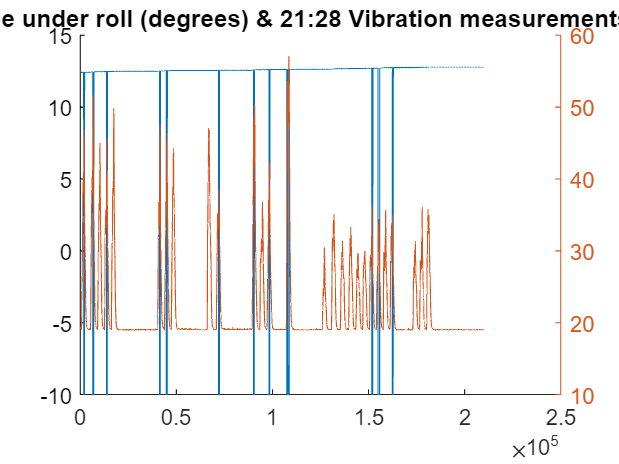

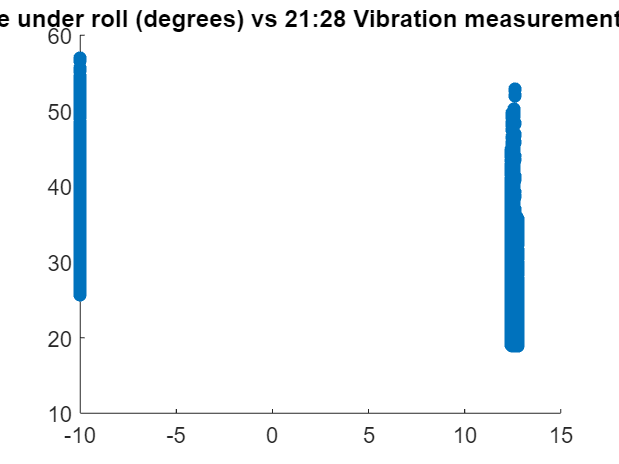

File: 1, Signal: 4, Signal: 6, R2: 0.271 
File: 1, Signal: 4, Signal: 7, R2: 0.0069 
File: 1, Signal: 4, Signal: 8, R2: 0.0108 
File: 1, Signal: 4, Signal: 9, R2: 0.00472 
File: 1, Signal: 4, Signal: 10, R2: 0.000353 
File: 1, Signal: 4, Signal: 11, R2: -Inf 
File: 1, Signal: 4, Signal: 12, R2: 0.000292 
File: 1, Signal: 5, Signal: 5, R2: 1 


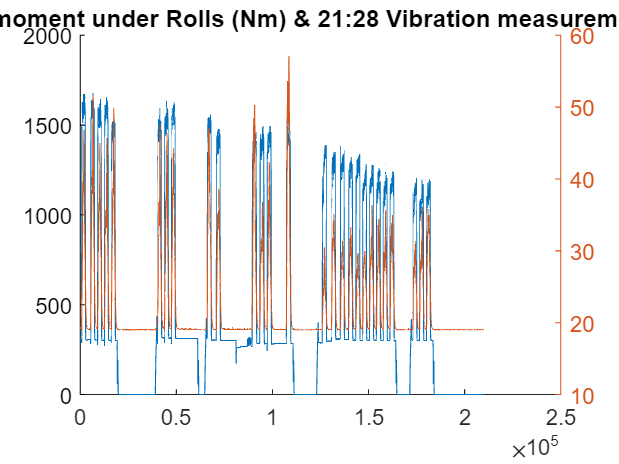

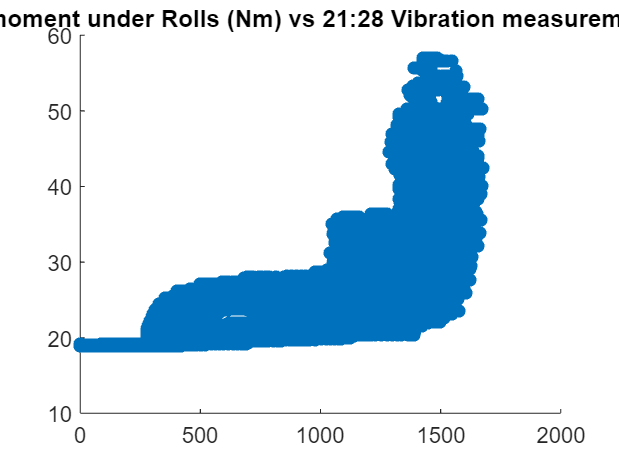

File: 1, Signal: 5, Signal: 6, R2: 0.737 
File: 1, Signal: 5, Signal: 7, R2: 0.0093 
File: 1, Signal: 5, Signal: 8, R2: 0.0434 
File: 1, Signal: 5, Signal: 9, R2: 0.0153 
File: 1, Signal: 5, Signal: 10, R2: 0.00189 
File: 1, Signal: 5, Signal: 11, R2: -Inf 
File: 1, Signal: 5, Signal: 12, R2: 0.0124 
File: 1, Signal: 6, Signal: 6, R2: 1 
File: 1, Signal: 6, Signal: 7, R2: 0.0127 
File: 1, Signal: 6, Signal: 8, R2: 0.0544 
File: 1, Signal: 6, Signal: 9, R2: 0.00647 
File: 1, Signal: 6, Signal: 10, R2: 0.00224 
File: 1, Signal: 6, Signal: 11, R2: -Inf 
File: 1, Signal: 6, Signal: 12, R2: 0.000306 
File: 1, Signal: 7, Signal: 7, R2: 1 


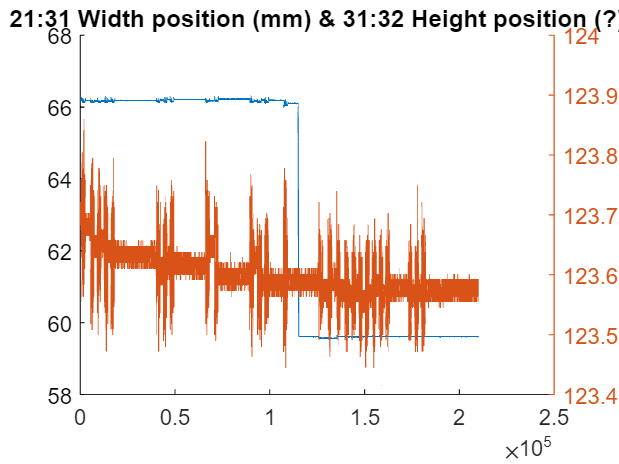

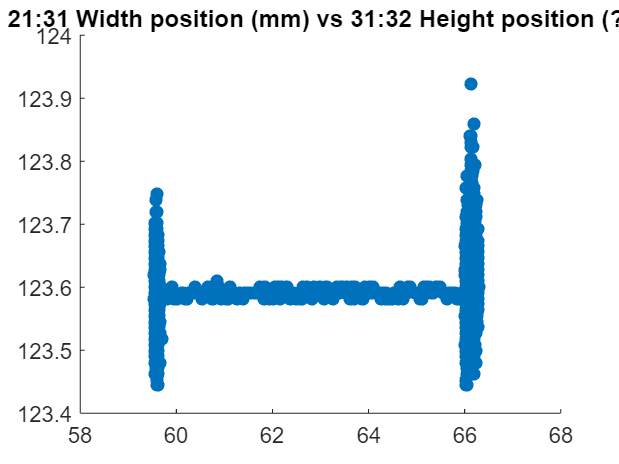

File: 1, Signal: 7, Signal: 8, R2: 0.353 


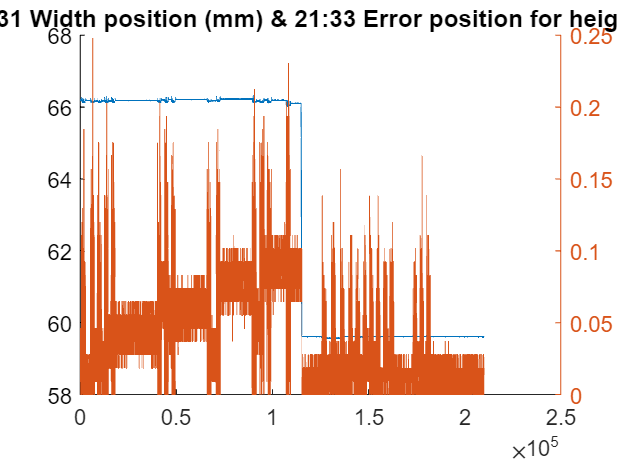

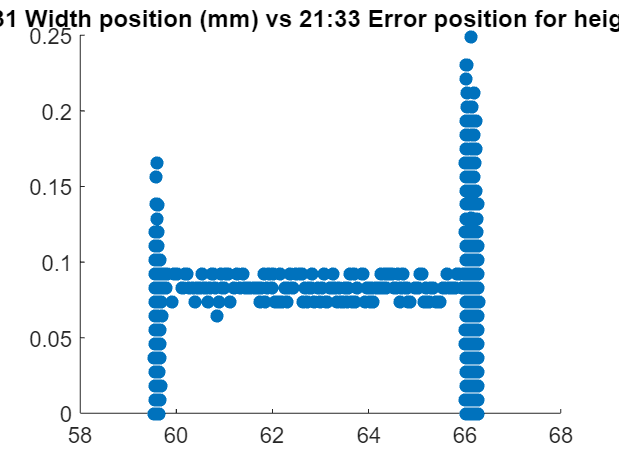

File: 1, Signal: 7, Signal: 9, R2: 0.469 
File: 1, Signal: 7, Signal: 10, R2: 0.0637 
File: 1, Signal: 7, Signal: 11, R2: -Inf 
File: 1, Signal: 7, Signal: 12, R2: 0.00517 
File: 1, Signal: 8, Signal: 8, R2: 1 
File: 1, Signal: 8, Signal: 9, R2: 2.1e-05 
File: 1, Signal: 8, Signal: 10, R2: 0.0213 
File: 1, Signal: 8, Signal: 11, R2: -Inf 
File: 1, Signal: 8, Signal: 12, R2: 0.000828 
File: 1, Signal: 9, Signal: 9, R2: 1 
File: 1, Signal: 9, Signal: 10, R2: 0.0616 
File: 1, Signal: 9, Signal: 11, R2: -Inf 
File: 1, Signal: 9, Signal: 12, R2: 0.0034 
File: 1, Signal: 10, Signal: 10, R2: 1 
File: 1, Signal: 10, Signal: 11, R2: -Inf 
File: 1, Signal: 10, Signal: 12, R2: 0.000191 
File: 1, Signal: 11, Signal: 11, R2: -Inf 
File: 1, Signal: 11, Signal: 12, R2: 1.14e-14 
File: 1, Signal: 12, Signal: 12, R2: 1 


LoadRawData();

warning('off','all')

rawDataArray = {numOfFiles};
for fileIndex = 1 : numOfFiles
    % Load the data for the current file
    rawDataStruct = load(subfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 
end

fileIndex = 1;
r2Val = [12,12];
%for fileIndex = 1 : numOfFiles
    for sensorIndex1 = 1 : 12
        for sensorIndex2 = sensorIndex1 : 12
            sig1 = rawDataArray{fileIndex}{sensorIndex1,2};
            sig2 = rawDataArray{fileIndex}{sensorIndex2,2};
            mdl = fitlm(sig1, sig2);
            R2 = mdl.Rsquared.Ordinary;
            if R2 > 0.2 && R2 < 0.8
                figure(); hold on; plot(sig1); yyaxis right; plot(sig2); 
                title(sensorNames(sensorIndex1) + " & " + sensorNames(sensorIndex2));
                figure(); scatter(sig1, sig2, "filled");
                title(sensorNames(sensorIndex1) + " vs " + sensorNames(sensorIndex2));
            end
            fprintf("File: %i, Signal: %i, Signal: %i, R2: %.3g \n", fileIndex,sensorIndex1, sensorIndex2, R2)
            r2Val(sensorIndex1, sensorIndex2) = R2;
        end
    end

%end

%% Plot table for the correlation of each raw signal in a particular file
arr = [1:1:12];
labels = arrayfun(@num2str, arr, 'UniformOutput', 0);
array2table(r2Val, 'VariableNames',	labels)

ans = 12×12 table
    1       2           3             4            5             6            7           8            9             10         11         12    
    _    _______    __________    _________    __________    _________    _________    ________    __________    __________    ____    __________

    1    0.11609      0.077339    0.0021121       0.06993     0.013875        0.163     0.13748     0.0018398     0.0096207    -Inf      0.045023
    0          1    0.00045767    0.0043065    0.00037914    0.0032602      0.78333     0.29805       0.35867      0.074298    -Inf    